# Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [<https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)>

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo.  [<http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)>

**System parameters**

nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)
epsilon = 0.1; % converge at order 5
% epsilon = 0.2; % converge at order 5

## Generate model

Building FE model


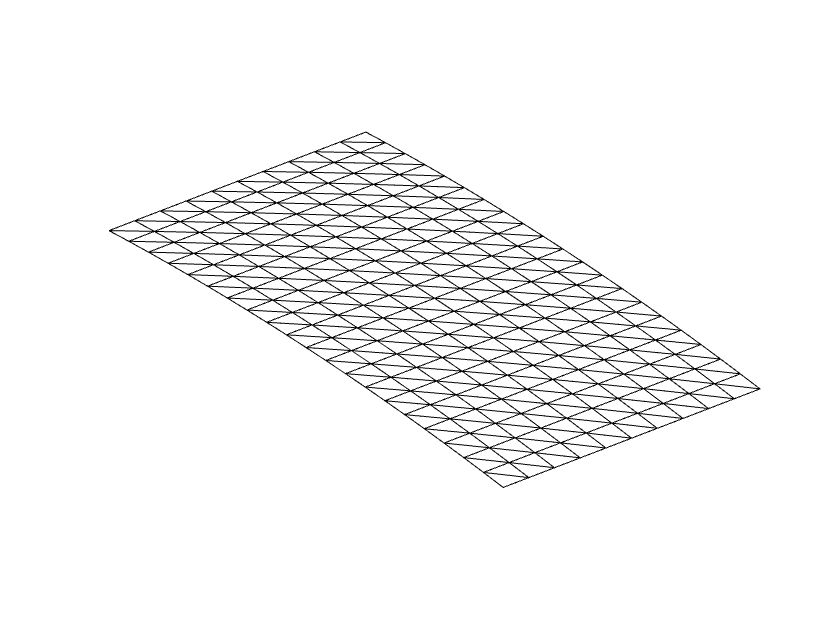

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  Show all properties


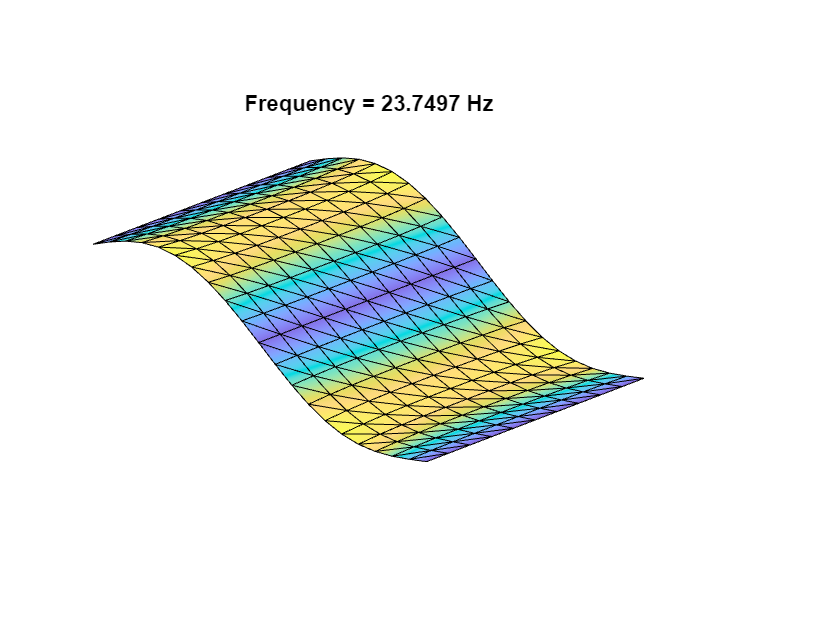

Using Rayleigh damping
Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:30


[M,C,K,fnl,f_0,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Dynamical system setup

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K}  & \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C}  & \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}\mathbf{f}^{ext}(\mathbf{\phi})\\\mathbf{0}\end{array}\right]$.

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} 
+ \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.102524e-03
modal damping ratio for 4 mode is 2.141338e-03
modal damping ratio for 5 mode is 2.369557e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4922i
  -0.0030 - 1.4922i
  -0.0060 + 2.9878i
  -0.0060 - 2.9878i
  -0.0071 + 3.3973i
  -0.0071 - 3.3973i
  -0.0076 + 3.5356i
  -0.0076 - 3.5356i
  -0.0101 + 4.2617i
  -0.0101 - 4.2617i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2,3,4]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     0     1     1     0
     1     0     1     1
     2     1     0     0
     1     0     0     1
     0     1     1     1
     1     2     0     0
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     0     0
     0     0     1     2
     1     1     0     1

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0030 + 1.4922i
  -0.0030 + 1.4922i
  -0.0030 + 1.4922i
  -0.0030 - 1.4922i
  -0.0030 - 1.4922i
  -0.0030 - 1.4922i
  -0.0060 + 2.9878i
  -0.0060 + 2.9878i
  -0.0060 + 2.9878i
  -0.0060 - 2.9878i
  -0.0060 - 2.9878i
  -0.0060 - 2.9878i

sigma_in = 3


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5;
set(S.Options, 'reltol', 0.5,'IRtol',0.05,'notation', 'multiindex')

choose frequency range around the first natural frequency

set(S.FRCOptions,'coordinates','polar','initialSolver','forward');
set(S.contOptions, 'h_min', 1e-2,'h_max',2,'PtMX',300);
omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.92 1.07];
mFreq = [1 2];

## Extract ridges and trenches of FRS in $\mathcal{L}_\infty$ norm

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     0     0
     0     0     1     2
     1     1     0     1
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     0     0
     0     0     1     2
     1     1     0     1
     1     0     1     0
     0     1     2     0
     3     0     0     0
     0     1     0     1
     0     3     0     0
     1     0     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0071 + 3.3973i
  -0.0071 + 3.3973i
  -0.0071 + 3.3973i
  -0.0071 - 3.3973i
  -0.0071 - 3.3973i
  -0.0071 - 3.3973i
  -0.0076 + 3.5356i
  -0.0076 + 3.5356i
  -0.0076 + 3.5356i
  -0.0076 - 3.5356i
  -0.0076 - 3.5356i
  -0.0076 - 3.5356i
  -0.0101 + 4.2617i
  -0.0101 + 4.2617i
  -0.0101 + 4.2617i
  -0.0101 - 4.2617i
  -0.0101 - 4.2617i
  -0.0101 - 4.2617i

sigma_out = 3
(

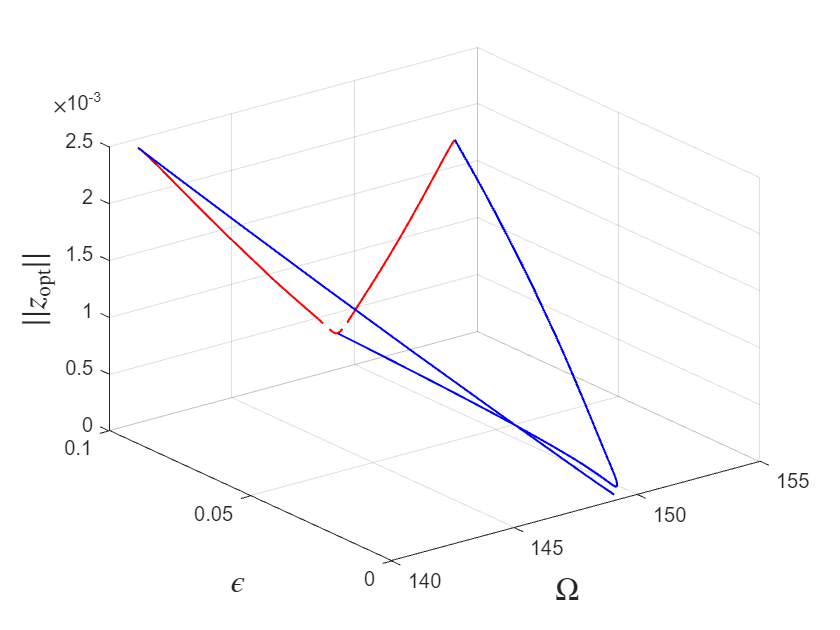

startdof1 = tic;
optdof = outdof(1);
set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',5, 'PtMX', 250);  % continuation setting
epsRange = [0.01 1]*epsilon;
parRange = {omegaRange,epsRange};
sol = ep_read_solution('','isol-5.ep',14);
set(S.FRCOptions,'coordinates','polar','initialSolver','fsolve');
set(S.Options, 'contribNonAuto',false, 'COMPtype', 'first'); 
set(S.FRSOptions, 'calFRS', true);
set(S.FRCOptions,'DBCobjnorm','linf','DBCstepFactor', [10 100]);
S.extract_ridges_trenches('bcssm-inf-dof1',masterModes,order,mFreq,parRange,outdof,optdof,{sol.p,sol.x});

timings.dof1 = toc(startdof1)

timings = struct with fields:
    dof1: 98.1621
    dof2: 98.8900


Change optdof and see what happens

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     0     0
     0     0     1     2
     1     1     0     1
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     0     0
     0     0     1     2
     1     1     0     1
     1     0     1     0
     0     1     2     0
     3     0     0     0
     0     1     0     1
     0     3     0     0
     1     0     0     2

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0071 + 3.3973i
  -0.0071 + 3.3973i
  -0.0071 + 3.3973i
  -0.0071 - 3.3973i
  -0.0071 - 3.3973i
  -0.0071 - 3.3973i
  -0.0076 + 3.5356i
  -0.0076 + 3.5356i
  -0.0076 + 3.5356i
  -0.0076 - 3.5356i
  -0.0076 - 3.5356i
  -0.0076 - 3.5356i
  -0.0101 + 4.2617i
  -0.0101 + 4.2617i
  -0.0101 + 4.2617i
  -0.0101 - 4.2617i
  -0.0101 - 4.2617i
  -0.0101 - 4.2617i

sigma_out = 3
(

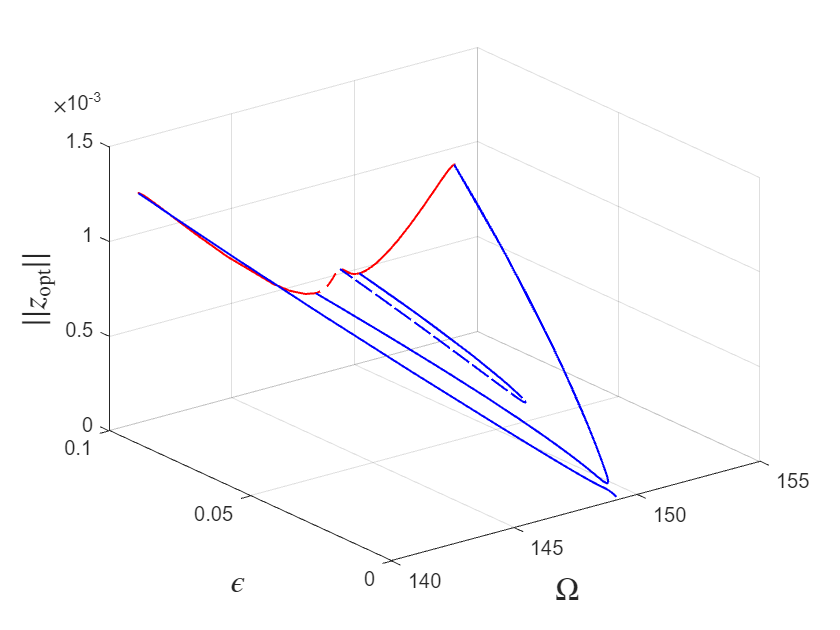

startdof2 = tic;
optdof = outdof(2);
S.extract_ridges_trenches('bcssm-inf-dof2',masterModes,order,mFreq,parRange,outdof,optdof,{sol.p,sol.x});

timings.dof2 = toc(startdof2)

timings = struct with fields:
    dof1: 98.1621
    dof2: 104.0156
